% Part A
fp = 0.5;   % Passband edge frequency (Normalized: 0.5 * pi rad/s)
fs = 0.6;   % Stopband edge frequency (Normalized: 0.6 * pi rad/s)
dev_p = 0.1;  % Passband tolerance (delta_p)
dev_s = 0.05; % Stopband tolerance (delta_s)

f_edges = [fp, fs]; 
mags = [1, 0];    % Desired magnitudes: 1 in passband, 0 in stopband
devs = [dev_p, dev_s]; 

% firpmord estimates the lowest order (n) that meets the specs.
[n, fo, ao, w] = firpmord(f_edges, mags, devs);

% firpm uses the estimated parameters to find the filter coefficients (b).
b = firpm(n, fo, ao, w);

fprintf('Part A: The lowest estimated order (n) is: %d\n', n);

Part A: The lowest estimated order (n) is: 17


fprintf('The length of the impulse response is: %d\n', length(b));

The length of the impulse response is: 18


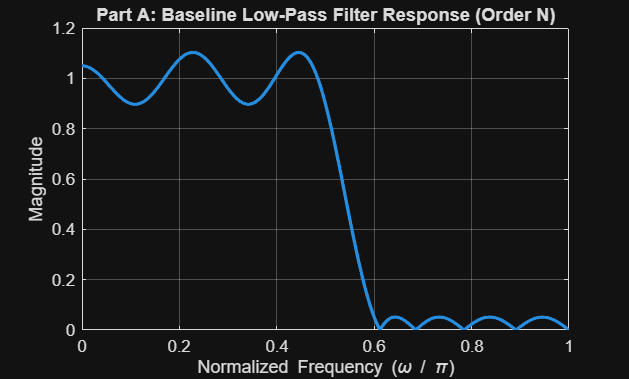


[h, w_rad] = freqz(b, 1, 1024); % 1024 frequency points
magnitude_response = abs(h);

figure(1);
plot(w_rad/pi, magnitude_response, 'LineWidth', 2);
title('Part A: Baseline Low-Pass Filter Response (Order N)');
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
grid on;

% Part B
dev_p_B = 0.05; 
fs = 0.6; % fs and fp remain the same

f_edges_B = [fp, fs]; 
devs_B = [dev_p_B, dev_s]; % Use the new dev_p

[n_B, fo_B, ao_B, w_B] = firpmord(f_edges_B, mags, devs_B);

b_B = firpm(n_B, fo_B, ao_B, w_B);
fprintf('\nPart B: Reducing Passband Ripple:\n');


Part B: Reducing Passband Ripple:


fprintf('The new estimated order (n) is: %d\n', n_B);

The new estimated order (n) is: 21


fprintf('The new length of the impulse response is: %d\n', length(b_B));

The new length of the impulse response is: 22


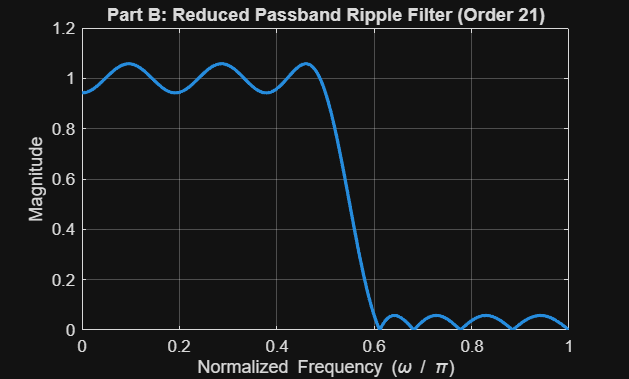


[h_B, ~] = freqz(b_B, 1, 1024);

figure(2); 
plot(w_rad/pi, abs(h_B), 'LineWidth', 2);
title(['Part B: Reduced Passband Ripple Filter (Order ', num2str(n_B), ')']); % Use n_B here
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
grid on;

% Part C
fs_C = 0.555; 
dev_p_C = 0.05;

f_edges_C = [fp, fs_C]; % Narrower transition band
devs_C = [dev_p_C, dev_s];

[n_C, fo_C, ao_C, w_C] = firpmord(f_edges_C, mags, devs_C);
b_C = firpm(n_C, fo_C, ao_C, w_C);

fprintf('\nPart C: Narrowing Transition Band:\n');


Part C: Narrowing Transition Band:


fprintf('The final estimated order (n) is: %d\n', n_C);

The final estimated order (n) is: 39


fprintf('The final length of the impulse response is: %d\n', length(b_C));

The final length of the impulse response is: 40


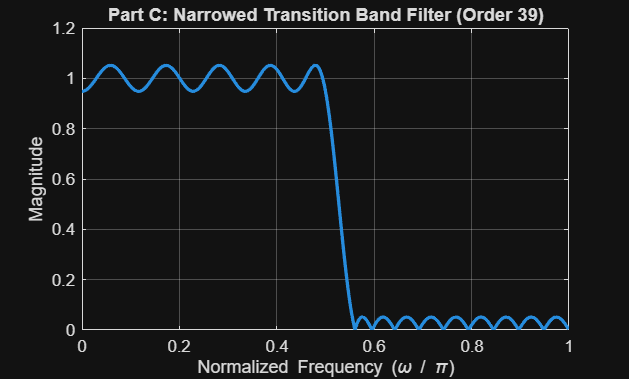


[h_C, ~] = freqz(b_C, 1, 1024);

% Assumes h_C and n_C were calculated and mag_C = abs(h_C)
figure(3); % Use a new figure number (e.g., 3)
plot(w_rad/pi, abs(h_C), 'LineWidth', 2);
title(['Part C: Narrowed Transition Band Filter (Order ', num2str(n_C), ')']); % Use n_C here
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
grid on;